## Compute Anti-aliasing Filter Components for ADC

Maximum source impedance of voltage source sampled by ADC. (source: STM32G474RE datasheet)

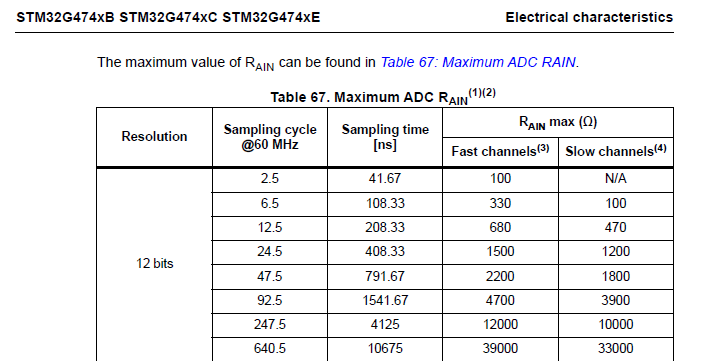

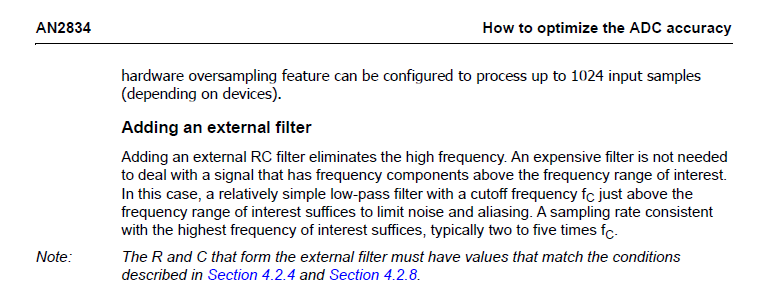

%f_aa_3db_tgt = SYSTEM.ADC.f_samp/10;      % Set anti-aliasing cut-off frequency to 1 decade less than sampling frequency

% Set common mode cut-off frequency to be a bit higher than the
% primary resonant frequency, Hz
f_cm_3db_tgt = SYSTEM.F_res_pri*5;

[Source](https://e2e.ti.com/blogs_/archives/b/precisionhub/posts/three-guidelines-for-designing-anti-aliasing-filters)

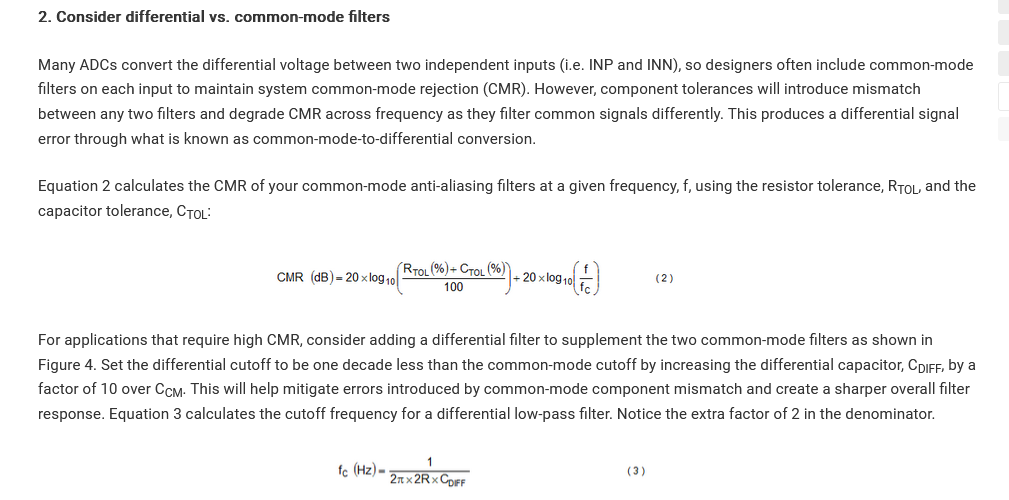

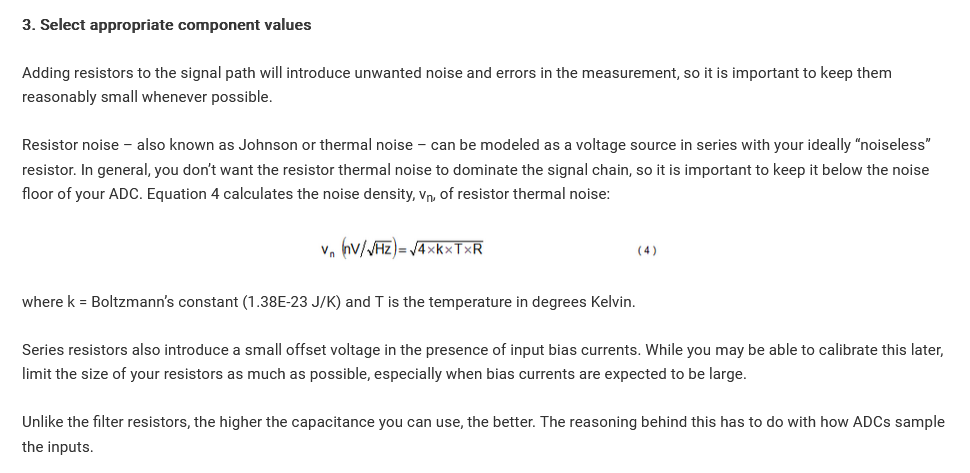

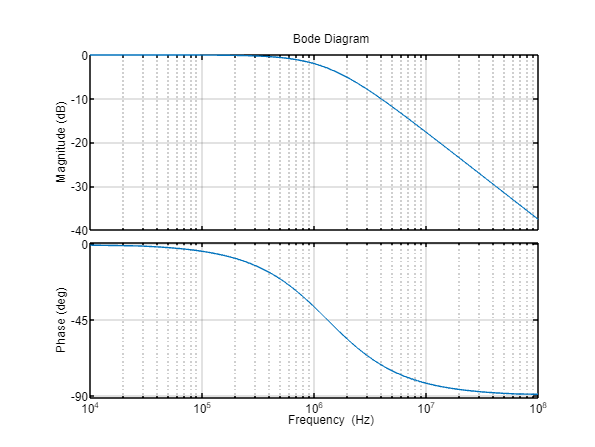

R_aa = 100; % Anti-aliasing LPF series R, ohms

% Compute the nominal anti-aliasing filter cap, F
C_aa_nom = 1/(f_cm_3db_tgt*2*pi*R_aa);
% Compute the standard value capacitor for the common-mode anti-aliasing filter, F
SYSTEM.ADC.C_cm = round63(C_aa_nom, 'E96', 'arithmetic');

% Compute actual common-mode cutoff frequency, Hz
SYSTEM.ADC.f_aa_cm_3db_actual = 1/(2*pi*R_aa*SYSTEM.ADC.C_cm);

% Bode plot of AA filter response
s = tf('s');
tau = R_aa*SYSTEM.ADC.C_cm;
H = 1/((s*tau) + 1);

%f_nyquist = SYSTEM.ADC.f_samp/2;
%freq_range = {10e3*2*pi, f_nyquist};

% Get the magnitude and phase of bode plot at primary resosnt frequency
[magnitude_abs, phase_deg, wout] = bode(H, SYSTEM.F_res_pri*2*pi);

% Process the output (if needed for single-input, single-output systems)
% Use 'squeeze' to remove singleton dimensions for easier handling
magnitude_abs = squeeze(magnitude_abs);
phase_deg = squeeze(phase_deg);

% Convert absolute magnitude to decibels (dB)
magnitude_dB = 20 * log10(magnitude_abs);

% Configure bode plot
opts = bodeoptions;
opts.FreqUnits = 'Hz'; % Set the frequency unit to Hertz
opts.Grid = 'on';
figure();
bode(H,opts);

%bode(H,freq_range,opts);

% % 3. Get the handles of the axes in the current figure
% % The children are typically returned with the top (magnitude) axis as the 
% % second element, and the bottom (phase) axis as the first or third, 
% % depending on MATLAB version and settings. A robust way is to use findobj.
% ax = findobj(gcf, 'Type', 'axes');
% 
% % Assign handles to specific axes (adjust index if needed, 
% % typical configuration is ax(2) for magnitude, ax(1) for phase)
% mag_ax = ax(2);
% phase_ax = ax(1); 
% 
% % 4. Add a vertical line to both plots at a specific frequency (e.g., 5 rad/s)
% % Specify the handle for the first argument of xline
% xline(mag_ax, 5, '--r', 'My Frequency'); % Dashed red line on magnitude plot
% xline(phase_ax, 5, '--r');               % Same line on phase plot

% Set differential filter capacitor to 5x common mode capacitor to
% set diff cut-off frequency 1 decade less than common mode cut-off
% frequency, this will help mitigate error from common mode component
% mismatch due to tolerance
C_diff_nom = SYSTEM.ADC.C_cm * 5;
SYSTEM.ADC.C_diff = round63(C_diff_nom, 'E96', 'arithmetic');

% Compute the differential filter cut-off frequency, Hz
SYSTEM.ADC.f_aa_diff_3db_actual = 1/(2*pi*2*R_aa*SYSTEM.ADC.C_diff);



## Show Results


fprintf("\n\n################ ADC Params BEGIN ##########################\n\n")



################ ADC Params BEGIN ##########################



fprintf("ADC sampling frequency: %0.4f MHz\n\n", SYSTEM.ADC.f_samp/1e6);

ADC sampling frequency: 2.6400 MHz



fprintf("Anti-aliasing filter R: %0.2f Ohm\n\n", R_aa);

Anti-aliasing filter R: 100.00 Ohm



fprintf("Common mode anti-aliasing filter C: %0.1f nF\n\n", SYSTEM.ADC.C_cm*1e9);

Anti-aliasing common-mode filter C: 1.2100 nF



fprintf("Common mode anti-aliasing filter cut-off frequency: %0.2f kHz\n\n", SYSTEM.ADC.f_aa_cm_3db_actual/1e3);

Common mode anti-aliasing filter cut-off frequency: 1315.33 kHz



fprintf("Common mode anti-aliasing filter magnitude @ %0.2f kHz: %0.2f dB\n\n",SYSTEM.F_res_pri/1e3,magnitude_dB);

Common mode nti-aliasing filter magnitude @ 264.00 kHz: -0.17 dB



fprintf("Common mode anti-aliasing filter phase @ %0.2f kHz: %0.2f deg\n\n",SYSTEM.F_res_pri/1e3,phase_deg);

Common mode anti-aliasing filter phase @ 264.00 kHz: -11.35 deg



fprintf("Differential anti-aliasing filter cut-off frequency: %0.2f kHz\n\n", SYSTEM.ADC.f_aa_diff_3db_actual/1e3);

Differential anti-aliasing filter cut-off frequency: 131.53 kHz



fprintf("Differential anti-aliasing filter C: %0.1f nF\n\n", SYSTEM.ADC.C_diff*1e9);
fprintf("################ ADC Params END ##########################\n\n")

################ ADC Params END ##########################

